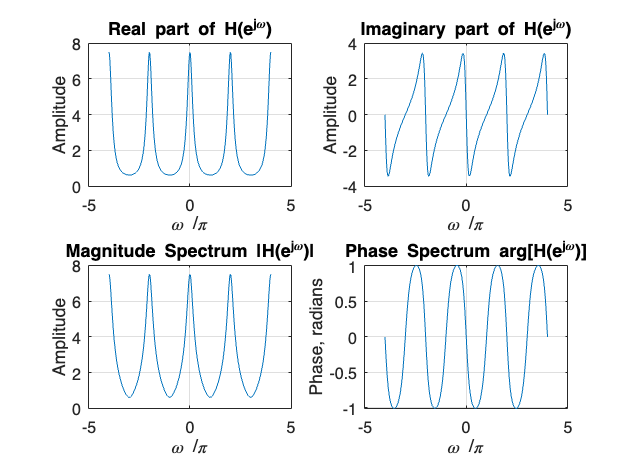

% Program P3_1
% Evaluation of the DTFT
clf;
% Compute the frequency samples of the DTFT
w = 0:8*pi/511:2*pi;
num = [2 1];den = [1 -0.6];
h = freqz(num, den, w);
% Plot the DTFT
subplot(2,2,1)
plot(w/pi,real(h));grid
title('Real part of H(e^{j\omega})')
xlabel('\omega /\pi');
ylabel('Amplitude');
subplot(2,2,2)
plot(w/pi,imag(h));grid
title('Imaginary part of H(e^{j\omega})')
xlabel('\omega /\pi');
ylabel('Amplitude');
% pause
subplot(2,2,3)
plot(w/pi,abs(h));grid
title('Magnitude Spectrum |H(e^{j\omega})|')
xlabel('\omega /\pi');
ylabel('Amplitude');
subplot(2,2,4)
plot(w/pi,angle(h));grid
title('Phase Spectrum arg[H(e^{j\omega})]')
xlabel('\omega /\pi');
ylabel('Phase, radians');